# Tutorial 1: Unsymmetric bending 

Problem 1:  

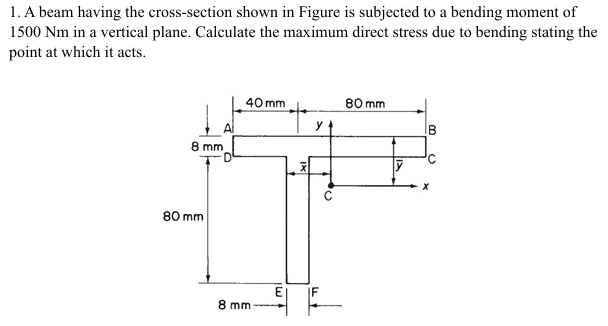

%% Finding out the CG 
% Area of each of the section in mm2
A1= 120*8; A2 = 8*80;
x_cg = (A1*60+A2*40)/(A1+A2);  % from left
y_cg = (A1*4+A2*48)/(A1+A2);  % from top
x_bar= x_cg-(40-4); y_bar=y_cg;  % according to the picture 
% floating-point with 2 decimals
fprintf('x_bar is %.4f and y_bar is %.4f\n', x_bar, y_bar);

x_bar is 16.0000 and y_bar is 21.6000


%%Finding Is in mm4
Ixx = (120*(8^3))/12 + A1*(4-y_cg)^2 + (8*80^3)/12 + A2*(48-y_cg)^2

Ixx = 1.0899e+06

Iyy = (8*120^3)/12 + A1*(60-x_cg)^2 + (80*8^3)/12 + A2*(40-x_cg)^2  % Calculate Iyy

Iyy = 1.3090e+06

Ixy = A1*(x_cg-60)*(-(y_cg-4)) + A2*(x_cg-40)*(48-y_cg)

Ixy = 337920

% As Only Vertical plane moment is acting so  
Mx = 1500000; My=0;
% Calculate the stress components
x_coeff = (My*Ixx - Mx*Ixy)/(Ixx*Iyy-Ixy^2)

x_coeff = -0.3862

y_coeff = (Mx*Iyy - My*Ixy)/(Ixx*Iyy-Ixy^2)

y_coeff = 1.4960

% Calculating the angle of the of nutral axis 
alpha = atan((My*Ixx - Mx*Ixy)/(Mx*Iyy - My*Ixy))*180/pi % in degrees

alpha = -14.4748

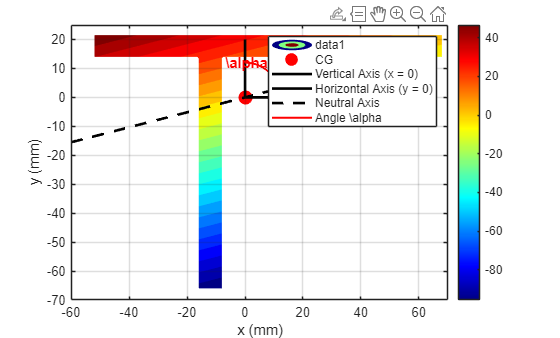

% making a function for the stress function 

sigma_z = @(x,y)(x_coeff*x + y_coeff*y);

[X, Y] = meshgrid(-60:0.5:70, -70:0.5:25);

% Masks for T-section geometry
inFlange = (X >= -x_cg) & (X <= 120-x_cg) & (Y >= y_cg-8) & (Y <= 21.6);
inWeb    = (X >= 36-x_cg) & (X <= 44-x_cg) & (Y >= -88+y_cg) & (Y <= y_cg-8);
inSection = inFlange | inWeb;

Z = sigma_z(X, Y);
Z(~inSection) = NaN; % Hide points outside the section

% Plotting
figure;
contourf(X, Y, Z, 25, 'LineColor', 'none');
hold on;
colormap(jet); colorbar;
title('\sigma_z Bending Stress Distribution (MPa)');
xlabel('x (mm)'); ylabel('y (mm)');

% CG and Limited Axes
plot(0, 0, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'DisplayName', 'CG');
plot([0, 0], [0, 20], 'k-', 'LineWidth', 2, 'DisplayName', 'Vertical Axis (x = 0)');
plot([0, 20], [0, 0], 'k-', 'LineWidth', 2, 'DisplayName', 'Horizontal Axis (y = 0)');

% Plot Neutral Axis
x_na = -60:1:60;
y_na = -tan(alpha * pi / 180) * x_na;
plot(x_na, y_na, 'k--', 'LineWidth', 2, 'DisplayName', 'Neutral Axis');

% =========================================================================
% NEW: ADD ANGLE ARC BETWEEN Y-AXIS AND NEUTRAL AXIS
% =========================================================================

% 1. Angles in polar coordinates (radians)
% Vertical axis (x = 0, y > 0) is at 90 degrees (pi/2)
theta_yAxis = pi / 2; 

% Angle of the upper/positive-y segment of the Neutral Axis
theta_NA = atan2(-tan(alpha * pi / 180) * 1, 1); 
if theta_NA < 0
    theta_NA = theta_NA + pi; % Ensure we take the branch in the upper half-plane
end

% 2. Generate arc points between the y-axis and Neutral Axis
r_arc = 12; % Radius of the arc (adjust size as needed)
t_arc = linspace(min(theta_yAxis, theta_NA), max(theta_yAxis, theta_NA), 100);
arc_x = r_arc * cos(t_arc);
arc_y = r_arc * sin(t_arc);

% Plot the arc line
plot(arc_x, arc_y, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Angle \alpha');

% 3. Add text label at the midpoint of the arc
mid_theta = (theta_yAxis + theta_NA) / 2;
label_x = (r_arc + 3) * cos(mid_theta);
label_y = (r_arc + 3) * sin(mid_theta);

text(label_x, label_y, sprintf('\\alpha = %.2f°', abs(alpha)), ...
    'FontSize', 11, 'FontWeight', 'bold', 'Color', 'b', ...
    'HorizontalAlignment', 'center');

% =========================================================================

axis equal; 
grid on;
legend('show');

sigma_z_E = sigma_z(36-x_cg,y_cg-88)

sigma_z_E = -93.1581

sigma_z_F = sigma_z(44-x_cg,y_cg-88)

sigma_z_F = -96.2478

## Prob 2: 

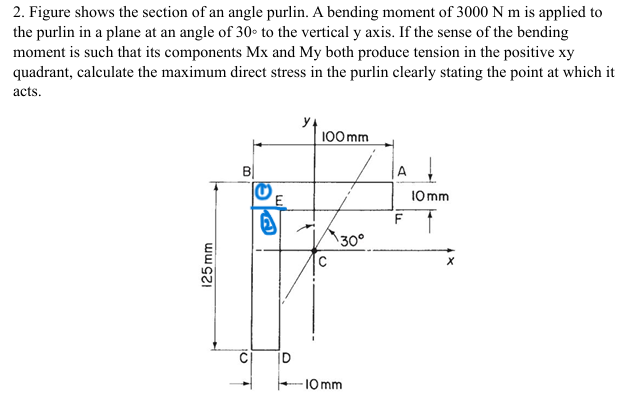

%% Finding out the CG 
% Area of each of the section in mm2
A1= 10*100; A2 = 115*10;
x_cg = (A1*50+A2*5)/(A1+A2);  % from left
y_cg = (A1*5+A2*(0.5*115 +10))/(A1+A2);  % from top
x_bar= x_cg; y_bar=y_cg;  % according to the picture ( FROM LEFT AND TOP) 
% floating-point with 2 decimals
fprintf('x_bar is %.4f and y_bar is %.4f\n', x_bar, y_bar);

x_bar is 25.9302 and y_bar is 38.4302


%%Finding Is in mm4
Ixx = (100*(10^3))/12 + A1*(5-y_cg)^2 + (10*115^3)/12 + A2*(115*0.5+10-y_cg)^2

Ixx = 3.3651e+06

Iyy = (10*100^3)/12 + A1*(50-x_cg)^2 + (115*10^3)/12 + A2*(5-x_cg)^2  % Calculate Iyy

Iyy = 1.9261e+06

Ixy = A1*(x_cg-50)*(-y_cg+5) + A2*(x_cg-5)*(115*0.5+10-y_cg)

Ixy = 1.5044e+06

## Prob 3: 

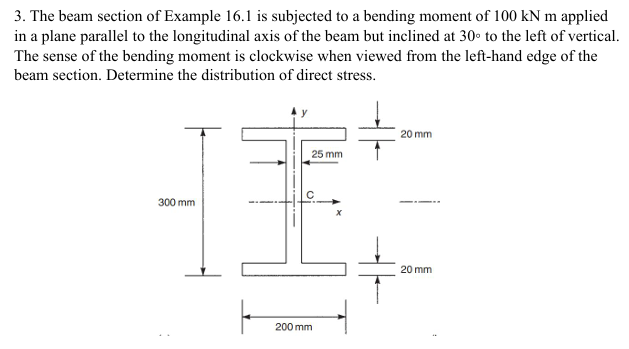

%% Finding out the CG 
% Area of each of the section in mm2
A1= 20*200; A2 = (300-40)*25;
x_cg = 100;  % from left
y_cg = 150;  % from top
x_bar= x_cg; y_bar=y_cg;  % according to the picture ( FROM LEFT AND TOP) 
% floating-point with 2 decimals
fprintf('x_bar is %.4f and y_bar is %.4f\n', x_bar, y_bar);

x_bar is 100.0000 and y_bar is 150.0000


%%Finding Is in mm4
Ixx = 2*(200*20^3/12 + A1*140^2) + (25*(300-40)^3)/12 

Ixx = 1.9368e+08

Iyy = 2*((20*200^3)/12 ) + ((300-40)*25^3)/12   % Calculate Iyy

Iyy = 2.7005e+07

Ixy = 0

Ixy = 0

## Prob 4:

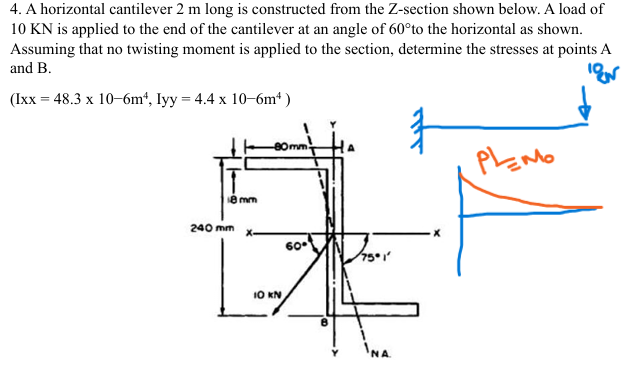

%% Finding out the CG 
% Area of each of the section in mm2
A1= 8*80; A2 = (240-16)*8;
x_cg = 80-4;  % from left
y_cg = 120;  % from top
x_bar= x_cg; y_bar=y_cg;  % according to the picture ( FROM LEFT AND TOP) 
% floating-point with 2 decimals
fprintf('x_bar is %.4f and y_bar is %.4f\n', x_bar, y_bar);

x_bar is 76.0000 and y_bar is 120.0000


% Calculate the second moments of area for the new sections
Ixx = 2*((80*8^3)/12 + A1*(y_cg-4)^2) + (8*(240-16)^3)/12 

Ixx = 24723456

Iyy = 2*((8*80^3)/12 + A1*(x_cg-40)^2) + ((240-16)*8^3)/12 

Iyy = 2351104

Ixy = A1*(x_cg-40)*(-y_cg+4) + A1*(-x_cg+40)*(y_cg-4)

Ixy = -5345280

## Prob 5:

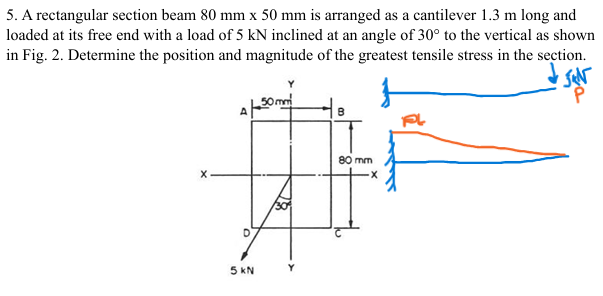

%% Finding out the CG 
% Area of each of the section in mm2
A1= 50*80 ;
x_cg = 25;  % from left
y_cg = 40;  % from top
x_bar= x_cg; y_bar=y_cg;  % according to the picture ( FROM LEFT AND TOP) 
% floating-point with 2 decimals
fprintf('x_bar is %.4f and y_bar is %.4f\n', x_bar, y_bar);

x_bar is 25.0000 and y_bar is 40.0000



% CAlculating the Is
Ixx = 50*80^3/12 

Ixx = 2.1333e+06

Iyy= 80*50^3/12

Iyy = 8.3333e+05

Ixy = 0

Ixy = 0

% moment calc
M = 5000*1.3*1000;  % acting on the plane at angle 30 with the -ve y axis in clockwise direction 
% So net moment will be in 60deg in CCW from -ve y axis 
Mx = M*sind(60); My=M*cosd(60);
% Calculate the stress components
x_coeff = (My*Ixx - Mx*Ixy)/(Ixx*Iyy-Ixy^2)

x_coeff = 3.9000

y_coeff = (Mx*Iyy - My*Ixy)/(Ixx*Iyy-Ixy^2)

y_coeff = 2.6387

% Calculating the angle of the of nutral axis 
alpha = atan((My*Ixx - Mx*Ixy)/(Mx*Iyy - My*Ixy))*180/pi % in degrees

alpha = 55.9184

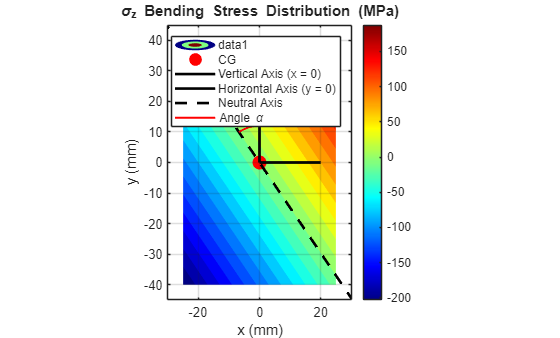

% making a function for the stress function 

sigma_z = @(x,y)(x_coeff*x + y_coeff*y);

[X, Y] = meshgrid(-30:0.5:30, -50:0.5:50);

% Masks for T-section geometry
inFlange = (X >= -x_cg) & (X <= x_cg) & (Y >= -y_cg) & (Y <= y_cg);

inSection = inFlange;

Z = sigma_z(X, Y);
Z(~inSection) = NaN; % Hide points outside the section

% Plotting
figure;
contourf(X, Y, Z, 25, 'LineColor', 'none');
hold on;
colormap(jet); colorbar;
title('\sigma_z Bending Stress Distribution (MPa)');
xlabel('x (mm)'); ylabel('y (mm)');

% CG and Limited Axes
plot(0, 0, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'DisplayName', 'CG');
plot([0, 0], [0, 20], 'k-', 'LineWidth', 2, 'DisplayName', 'Vertical Axis (x = 0)');
plot([0, 20], [0, 0], 'k-', 'LineWidth', 2, 'DisplayName', 'Horizontal Axis (y = 0)');

% Plot Neutral Axis
x_na = -60:1:60;
y_na = -tan(alpha * pi / 180) * x_na;
plot(x_na, y_na, 'k--', 'LineWidth', 2, 'DisplayName', 'Neutral Axis');

% =========================================================================
% NEW: ADD ANGLE ARC BETWEEN Y-AXIS AND NEUTRAL AXIS
% =========================================================================

% 1. Angles in polar coordinates (radians)
% Vertical axis (x = 0, y > 0) is at 90 degrees (pi/2)
theta_yAxis = pi / 2; 

% Angle of the upper/positive-y segment of the Neutral Axis
theta_NA = atan2(-tan(alpha * pi / 180) * 1, 1); 
if theta_NA < 0
    theta_NA = theta_NA + pi; % Ensure we take the branch in the upper half-plane
end

% 2. Generate arc points between the y-axis and Neutral Axis
r_arc = 12; % Radius of the arc (adjust size as needed)
t_arc = linspace(min(theta_yAxis, theta_NA), max(theta_yAxis, theta_NA), 100);
arc_x = r_arc * cos(t_arc);
arc_y = r_arc * sin(t_arc);

% Plot the arc line
plot(arc_x, arc_y, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Angle \alpha');

% 3. Add text label at the midpoint of the arc
mid_theta = (theta_yAxis + theta_NA) / 2;
label_x = (r_arc + 3) * cos(mid_theta);
label_y = (r_arc + 3) * sin(mid_theta);

text(label_x, label_y, sprintf('\\alpha = %.2f°', abs(alpha)), ...
    'FontSize', 11, 'FontWeight', 'bold', 'Color', 'b', ...
    'HorizontalAlignment', 'center');

% =========================================================================

axis equal; 
grid on;
legend('show');

xlim([-30 30])
ylim([-45 45])

% FInding some stress points (MPa)
sigma_z_B = sigma_z(x_cg,y_cg)

sigma_z_B = 203.0468

sigma_z_D = sigma_z(-x_cg,-y_cg)

sigma_z_D = -203.0468

## Prob 6 :

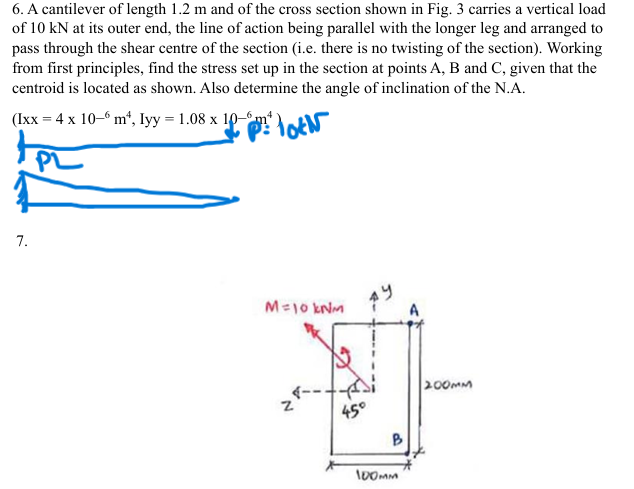

%finding CG
x_cg = 2;
y_cg  =2 ;




## Problem 7:

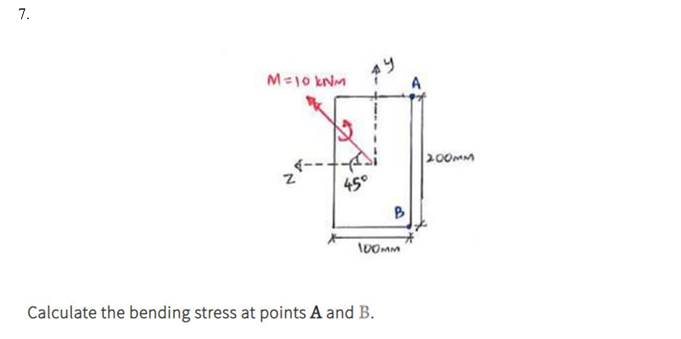

%% Finding out the CG 
% Area of each of the section in mm2
A1= 50*80 ;
z_cg = 50;  % from left
y_cg = 100;  % from top
z_bar= z_cg; y_bar=y_cg;  % according to the picture ( FROM LEFT AND TOP) 
% floating-point with 2 decimals
fprintf('x_bar is %.4f and y_bar is %.4f\n', z_bar, y_bar);

x_bar is 50.0000 and y_bar is 100.0000



% CAlculating the Is
Izz = 100*200^3/12 

Izz = 6.6667e+07

Iyy= 200*100^3/12

Iyy = 1.6667e+07

Iyz = 0

Iyz = 0

% moment calc (N_mm)
M = 10000*1000;  % acting on the plane at angle 30 with the -ve y axis in clockwise direction 
% So net moment will be in 60deg in CCW from -ve y axis 
Mz = M*sind(45); My=M*cosd(45);
% Calculate the stress components
y_coeff = -(Mz*Iyy + My*Iyz)/(-Izz*Iyy + Iyz^2)

y_coeff = 0.1061

z_coeff = (-Mz*Iyz - My*Izz)/(-Izz*Iyy + Iyz^2)

z_coeff = 0.4243

% Calculating the angle of the of nutral axis 
alpha = atan((Mz*Iyy + My*Iyz)/(Mz*Iyz + My*Izz))*180/pi % in degrees

alpha = 14.0362

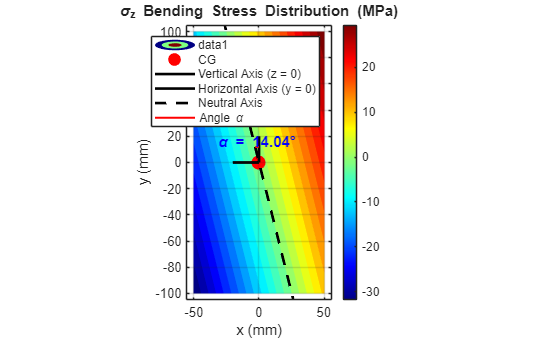

% making a function for the stress function 

sigma_z = @(z,y)(z_coeff*z + y_coeff*y);

[Z, Y] = meshgrid(-55:0.5: 55, -105:0.5:105);

% Masks for T-section geometry
inFlange = (Z >= -z_cg) & (Z <= z_cg) & (Y >= -y_cg) & (Y <= y_cg);

inSection = inFlange;

X = sigma_z(Z, Y);
X(~inSection) = NaN; % Hide points outside the section

% Plotting
figure;
contourf(Z, Y, X, 25, 'LineColor', 'none');
hold on;
colormap(jet); colorbar;
title('\sigma_z Bending Stress Distribution (MPa)');
xlabel('x (mm)'); ylabel('y (mm)');

% CG and Limited Axes
plot(0, 0, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'DisplayName', 'CG');
plot([0, 0], [0, 20], 'k-', 'LineWidth', 2, 'DisplayName', 'Vertical Axis (z = 0)');
plot([0, -20], [0, 0], 'k-', 'LineWidth', 2, 'DisplayName', 'Horizontal Axis (y = 0)');

% Plot Neutral Axis
z_na = -60:1:60;
y_na = -tan((pi/2)-alpha * pi / 180) * z_na;
plot(z_na, y_na, 'k--', 'LineWidth', 2, 'DisplayName', 'Neutral Axis');

% =========================================================================
% NEW: ADD ANGLE ARC BETWEEN Y-AXIS AND NEUTRAL AXIS
% =========================================================================

% 1. Angles in polar coordinates (radians)
% Vertical axis (x = 0, y > 0) is at 90 degrees (pi/2)
theta_yAxis = pi / 2; 

% Angle of the upper/positive-y segment of the Neutral Axis
theta_NA = atan2(-tan((pi/2) -alpha * pi / 180) * 1, 1); 
if theta_NA < 0
    theta_NA = theta_NA + pi; % Ensure we take the branch in the upper half-plane
end

% 2. Generate arc points between the y-axis and Neutral Axis
r_arc = 12; % Radius of the arc (adjust size as needed)
t_arc = linspace(min(theta_yAxis, theta_NA), max(theta_yAxis, theta_NA), 100);
arc_x = r_arc * cos(t_arc);
arc_y = r_arc * sin(t_arc);

% Plot the arc line
plot(arc_x, arc_y, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Angle \alpha');

% 3. Add text label at the midpoint of the arc
mid_theta = (theta_yAxis + theta_NA) / 2;
label_x = (r_arc + 3) * cos(mid_theta);
label_y = (r_arc + 3) * sin(mid_theta);

text(label_x, label_y, sprintf('\\alpha = %.2f°', abs(alpha)), ...
    'FontSize', 11, 'FontWeight', 'bold', 'Color', 'b', ...
    'HorizontalAlignment', 'center');

% =========================================================================

axis equal; 
grid on;
legend('show');

xlim([-55 55])
ylim([-105 105])

% FInding some stress points (MPa)
sigma_x_A = sigma_z(z_cg,y_cg)

sigma_x_A = 31.8198

sigma_x_B = sigma_z(z_cg,-y_cg)

sigma_x_B = 10.6066

## Problem 8:

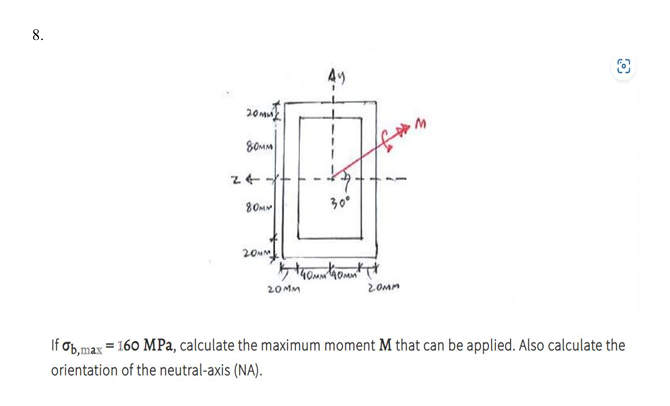

%% Finding out the CG 
% Area of each of the section in mm2
A1= 200*120 ; A2= -160*80;
z_cg = 60*(A1 + A2)/(A1+A2);  % from left
y_cg = (A1*100 + A2*100)/(A1+A2);  % from top
z_bar= z_cg; y_bar=y_cg;  % according to the picture ( FROM LEFT AND TOP) 
% floating-point with 2 decimals
fprintf('z_bar is %.4f and y_bar is %.4f\n', z_bar, y_bar);

z_bar is 60.0000 and y_bar is 100.0000



% CAlculating the Is
Izz = 120*200^3/12 - 80*160^3/12

Izz = 5.2693e+07

Iyy= 120^3*200^1/12 - 80^3*160^1/12

Iyy = 2.1973e+07

Iyz = 0

Iyz = 0

% moment calc (N_mm)
M = 10000*1000;  % acting on the plane at angle 30 with the -ve y axis in clockwise direction 
% So net moment will be in 60deg in CCW from -ve y axis 
Mz = M*sind(45); My=M*cosd(45);
% Calculate the stress components
y_coeff = -(Mz*Iyy + My*Iyz)/(-Izz*Iyy + Iyz^2)

y_coeff = 0.1342

z_coeff = (-Mz*Iyz - My*Izz)/(-Izz*Iyy + Iyz^2)

z_coeff = 0.3218

% Calculating the angle of the of nutral axis 
alpha = atan((Mz*Iyy + My*Iyz)/(Mz*Iyz + My*Izz))*180/pi % in degrees

alpha = 22.6363

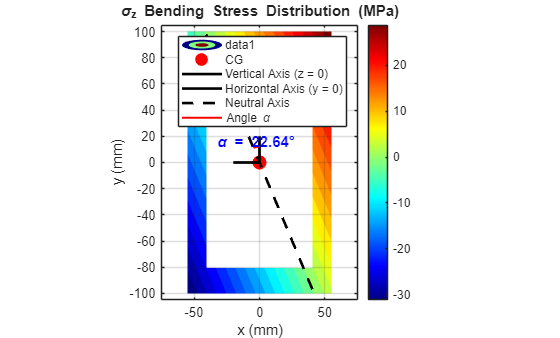

% making a function for the stress function 

sigma_z = @(z,y)(z_coeff*z + y_coeff*y);

[Z, Y] = meshgrid(-55:0.5: 55, -105:0.5:105);

% Masks for T-section geometry
inFlange = (Z >= -z_cg) & (Z <= z_cg) & (Y >= -y_cg) & (Y <= y_cg);
outFlange = (Z >= -(z_cg-20)) & (Z <= (z_cg-20)) & (Y >= -(y_cg-20)) & (Y <= (y_cg-20));
inSection = inFlange & ~outFlange ;

X = sigma_z(Z, Y);
X(~inSection) = NaN; % Hide points outside the section

% Plotting
figure;
contourf(Z, Y, X, 25, 'LineColor', 'none');
hold on;
colormap(jet); colorbar;
title('\sigma_z Bending Stress Distribution (MPa)');
xlabel('x (mm)'); ylabel('y (mm)');

% CG and Limited Axes
plot(0, 0, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'DisplayName', 'CG');
plot([0, 0], [0, 20], 'k-', 'LineWidth', 2, 'DisplayName', 'Vertical Axis (z = 0)');
plot([0, -20], [0, 0], 'k-', 'LineWidth', 2, 'DisplayName', 'Horizontal Axis (y = 0)');

% Plot Neutral Axis
z_na = -60:1:60;
y_na = -tan((pi/2)-alpha * pi / 180) * z_na;
plot(z_na, y_na, 'k--', 'LineWidth', 2, 'DisplayName', 'Neutral Axis');

% =========================================================================
% NEW: ADD ANGLE ARC BETWEEN Y-AXIS AND NEUTRAL AXIS
% =========================================================================

% 1. Angles in polar coordinates (radians)
% Vertical axis (x = 0, y > 0) is at 90 degrees (pi/2)
theta_yAxis = pi / 2; 

% Angle of the upper/positive-y segment of the Neutral Axis
theta_NA = atan2(-tan((pi/2) -alpha * pi / 180) * 1, 1); 
if theta_NA < 0
    theta_NA = theta_NA + pi; % Ensure we take the branch in the upper half-plane
end

% 2. Generate arc points between the y-axis and Neutral Axis
r_arc = 12; % Radius of the arc (adjust size as needed)
t_arc = linspace(min(theta_yAxis, theta_NA), max(theta_yAxis, theta_NA), 100);
arc_x = r_arc * cos(t_arc);
arc_y = r_arc * sin(t_arc);

% Plot the arc line
plot(arc_x, arc_y, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Angle \alpha');

% Add text label at the midpoint of the arc
mid_theta = (theta_yAxis + theta_NA) / 2;
label_x = (r_arc + 3) * cos(mid_theta);
label_y = (r_arc + 3) * sin(mid_theta);

text(label_x, label_y, sprintf('\\alpha = %.2f°', abs(alpha)), ...
    'FontSize', 11, 'FontWeight', 'bold', 'Color', 'b', ...
    'HorizontalAlignment', 'center');

% =========================================================================

% 1. Set equal axis aspect ratio (1 unit X = 1 unit Y visually)
axis equal; 
grid on;
legend('show');

% 2. Match the axis limits range (210 units total on both X and Y)
xlim([-75 75]); 
ylim([-105 105]);

% 3. Force the physical plotting box to be a square
gca1 = gca;
gca1.PlotBoxAspectRatio = [1 1 1];

## PROBLEM 9:

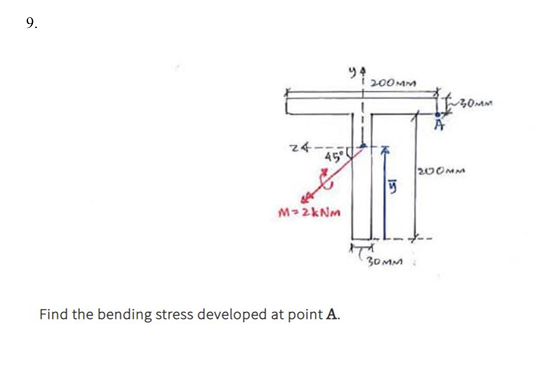

%% Finding out the CG 
% Area of each of the section in mm2
A1= 200*30 ; A2= 200*30;
z_cg = (A1*100 + A2*100)/(A1+A2);  % from left
y_cg = (A1*15 + A2*(30+100))/(A1+A2);  % from top
z_bar= z_cg; y_bar=230-y_cg;  % according to the picture ( FROM LEFT AND TOP) 
% floating-point with 2 decimals
fprintf('z_bar is %.4f and y_bar is %.4f\n', z_bar, y_bar);

z_bar is 100.0000 and y_bar is 157.5000



% CAlculating the Is
Izz = 200*30^3/12 + A1*(15-y_cg)^2 +  30*200^3/12 +A2*(30+100-y_cg)^2

Izz = 60125000

Iyy= 200^3*30^1/12 + 30^3*200^1/12

Iyy = 20450000

Iyz = 0

Iyz = 0

% moment calc (N_mm)
M = 2000*1000;  % acting on the plane at angle 30 with the -ve y axis in clockwise direction 
% So net moment will be in 60deg in CCW from -ve y axis 
My = -M*sind(45); Mz=M*cosd(45);
% Calculate the stress components
y_coeff = -(Mz*Iyy + My*Iyz)/(-Izz*Iyy + Iyz^2)

y_coeff = 0.0235

z_coeff = (-Mz*Iyz - My*Izz)/(-Izz*Iyy + Iyz^2)

z_coeff = -0.0692

% Calculating the angle of the of nutral axis 
alpha = atan((Mz*Iyy + My*Iyz)/(Mz*Iyz + My*Izz))*180/pi % in degrees

alpha = -18.7844

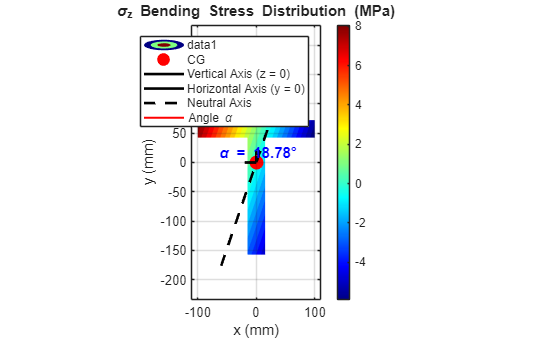

% making a function for the stress function 

sigma_z = @(z,y)(z_coeff*z + y_coeff*y);

[Z, Y] = meshgrid(-110:0.5: 110, -160:0.5:80);

% Masks for T-section geometry
inFlange = (Z >= -z_cg) & (Z <= z_cg) & (Y >= (y_cg-30)) & (Y <= y_cg);
WEDGE = (Z >= -(15)) & (Z <= (15)) & (Y >= -(y_bar)) & (Y <= (200-y_bar));
inSection = inFlange |WEDGE  ;

X = sigma_z(Z, Y);
X(~inSection) = NaN; % Hide points outside the section

% Plotting
figure;
contourf(Z, Y, X, 25, 'LineColor', 'none');
hold on;
colormap(jet); colorbar;
title('\sigma_z Bending Stress Distribution (MPa)');
xlabel('x (mm)'); ylabel('y (mm)');

% CG and Limited Axes
plot(0, 0, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'DisplayName', 'CG');
plot([0, 0], [0, 20], 'k-', 'LineWidth', 2, 'DisplayName', 'Vertical Axis (z = 0)');
plot([0, -20], [0, 0], 'k-', 'LineWidth', 2, 'DisplayName', 'Horizontal Axis (y = 0)');

% Plot Neutral Axis
z_na = -60:1:60;
y_na = -tan((pi/2)-alpha * pi / 180) * z_na;
plot(z_na, y_na, 'k--', 'LineWidth', 2, 'DisplayName', 'Neutral Axis');

% =========================================================================
% NEW: ADD ANGLE ARC BETWEEN Y-AXIS AND NEUTRAL AXIS
% =========================================================================

% 1. Angles in polar coordinates (radians)
% Vertical axis (x = 0, y > 0) is at 90 degrees (pi/2)
theta_yAxis = pi / 2; 

% Angle of the upper/positive-y segment of the Neutral Axis
theta_NA = atan2(-tan((pi/2) -alpha * pi / 180) * 1, 1); 
if theta_NA < 0
    theta_NA = theta_NA + pi; % Ensure we take the branch in the upper half-plane
end

% 2. Generate arc points between the y-axis and Neutral Axis
r_arc = 12; % Radius of the arc (adjust size as needed)
t_arc = linspace(min(theta_yAxis, theta_NA), max(theta_yAxis, theta_NA), 100);
arc_x = r_arc * cos(t_arc);
arc_y = r_arc * sin(t_arc);

% Plot the arc line
plot(arc_x, arc_y, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Angle \alpha');

% Add text label at the midpoint of the arc
mid_theta = (theta_yAxis + theta_NA) / 2;
label_x = (r_arc + 3) * cos(mid_theta);
label_y = (r_arc + 3) * sin(mid_theta);

text(label_x, label_y, sprintf('\\alpha = %.2f°', abs(alpha)), ...
    'FontSize', 11, 'FontWeight', 'bold', 'Color', 'b', ...
    'HorizontalAlignment', 'center');

% =========================================================================

% 1. Set equal axis aspect ratio (1 unit X = 1 unit Y visually)
axis equal; 
grid on;
legend('show');

% 2. Match the axis limits range (210 units total on both X and Y)
xlim([-75 75]); 
ylim([-235 235]);

% 3. Force the physical plotting box to be a square
gca1 = gca;
gca1.PlotBoxAspectRatio = [1 1 1];

xlim([-110 109])
ylim([-235 235])

% FInding some stress points (MPa)
sigma_x_A = sigma_z(z_cg,y_cg-30)

sigma_x_A = -5.9158